# CSSC PID Workshop

## Introduction to the Coupled-Tank System

The Coupled Tanks plant is a “Two-Tank” system consisting of a single pump, two cylindrical tanks, and a water basin. For the purposes of this workshop will be only working with the tank-2. The goal of this workshop is to design a controller for the Coupled-Tank System that can track a reference height that we have specified. This is a very common control problem for liquid-level systems present in industrial applications found in the processing systems of petro-chemical, paper making, and water treatment plants. The schematic below shows the system that you will be working with today. The pump takes in a **voltage input (control)** that then pumps water from the water basin below upwards into tank-2. There is a pressure transducer sensor located at the bottom of the tank that is calibrated to measure the level of water present in the tank, giving us a **measurement (feedback)**  that can be used for designing a controller. 

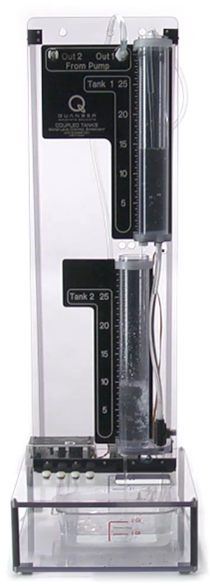       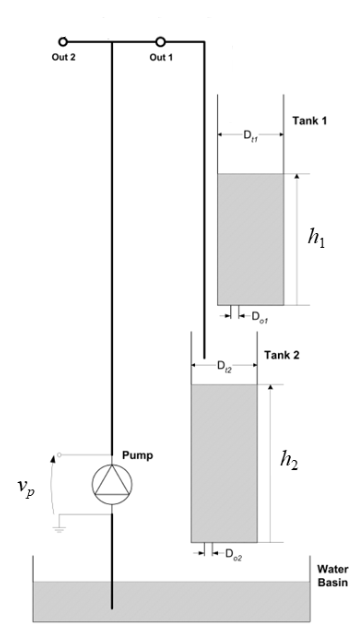

Now let us familiarize ourselves with using the coupled tanks plant experimental system that you will be designing the PID controller for. You will need to follow the following steps to turn on the experimental system and run the PID controller that you have tuned. Make sure that you run the script in MATLAB first before you **Build** and **Start** the system from Simulink.

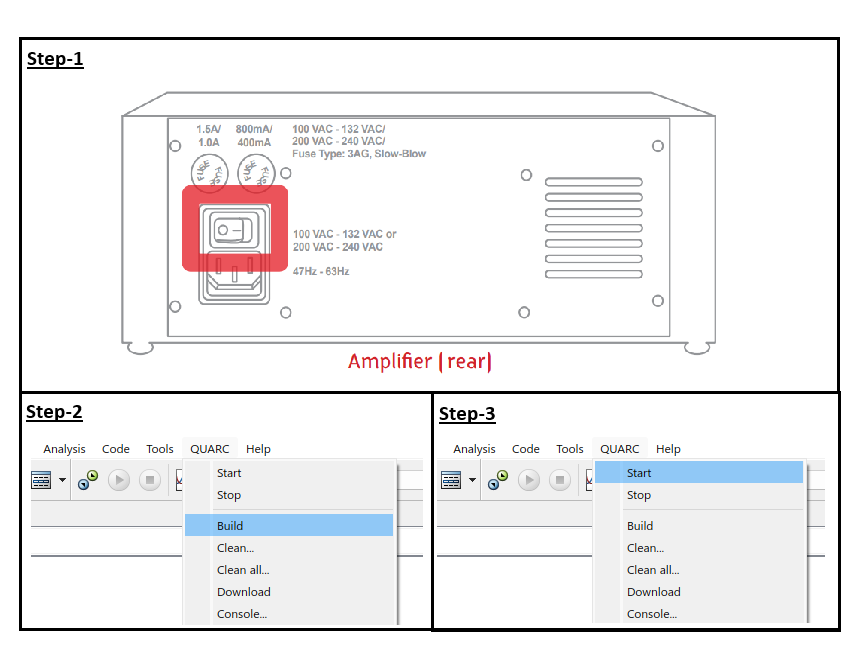

## PID Manual Tuning

 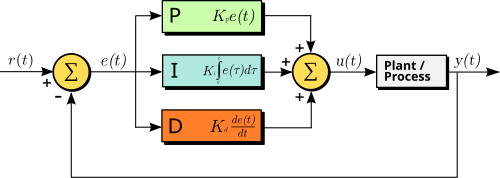

In this section, we will begin by first understanding how control works in general by getting an intuition by controlling the pump manually. Next we use the same intuition to tune the **P - proportional**, **I - integral**, and **D - derivative** gains of the PID controller.

- 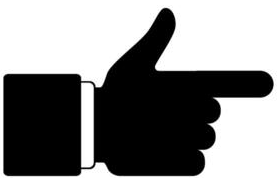  Set a reference height of 15cm by sliding the **Ref** slider.

-   Use **Open loop** control mode and the pump input **V** slider to control the pump and try tracking 15cm manually.

-   Now tune the **P**, **I**, and **D** gains by sliding their respective sliders to achieve reference tracking at 15cm.


C = 1; % Control Mode


Ref = 0; % Reference Height
V = 0; % Pump Input Voltage


P =0;
I =0;
D =0;


set_param(gcs, 'SimulationCommand', 'update');

## Ziegler-Nichols PID Tuning

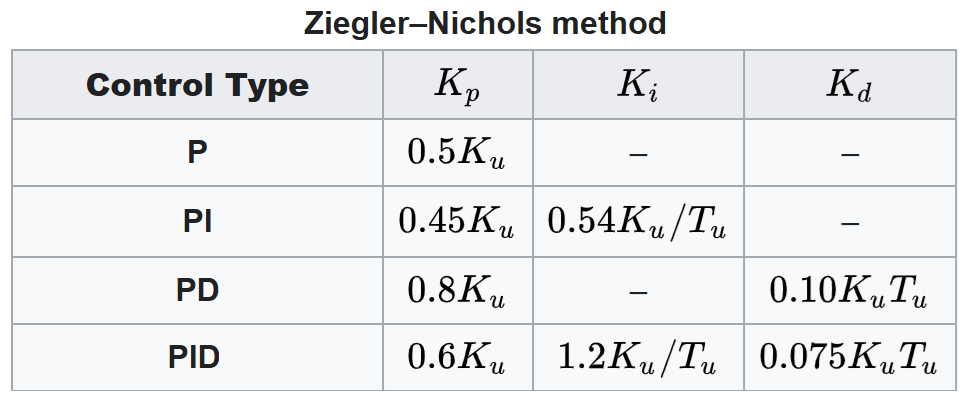

In this section we will be auto-tuning the PID gains using the Ziegler-Nichols PID Tuning method.

-   Start by increasing the **P** gain until the system starts oscillating (becomes marginally stable) around the 15cm reference point. Set **Ku** equal to the corresponding P gain value.

-   Now use the scope in the Simulink environment to find the time period of oscillation and set **Tu** equal to this value. 

-   Change the tuning mode to **PID Tuning** and run the experimental system to see it the new gains work. You can also change the controller type from the drop down selector.


C = 1;  % Control Mode
T = 0;  % Tuning Mode

Ref = 0; % Reference Height
V = 0; % Pump Input Voltage
P =0; % P gain for finding Ku & Tu

controller_type = 'P';

Ku = 0;
Tu = 0;

if T == 1
    switch controller_type
        case 'P'
            P = 0.5*Ku;
            I = 0;
            D = 0;
        case 'PI'
            P = 0.45*Ku;
            I = 0.54*Ku/Tu;
            D = 0;
        case 'PID'
            P = 0.2*Ku;
            I = 0.4*Ku/Tu;
            D = 0.066*Ku*Tu;
    end
end

set_param(gcs, 'SimulationCommand', 'update');

## Integral Anti-Windup

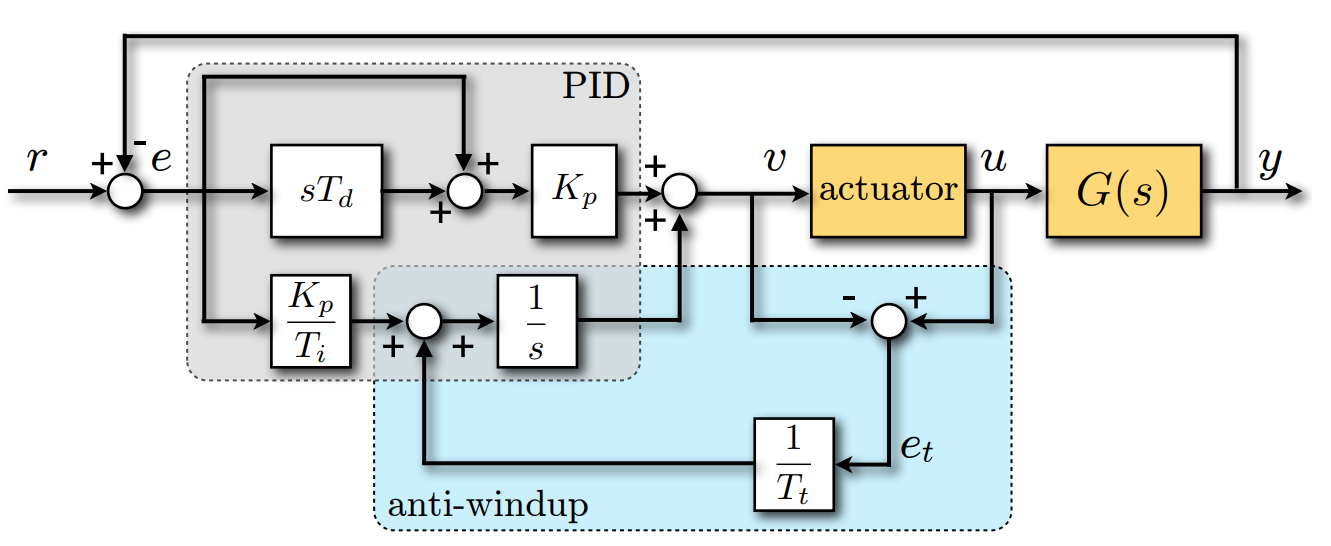

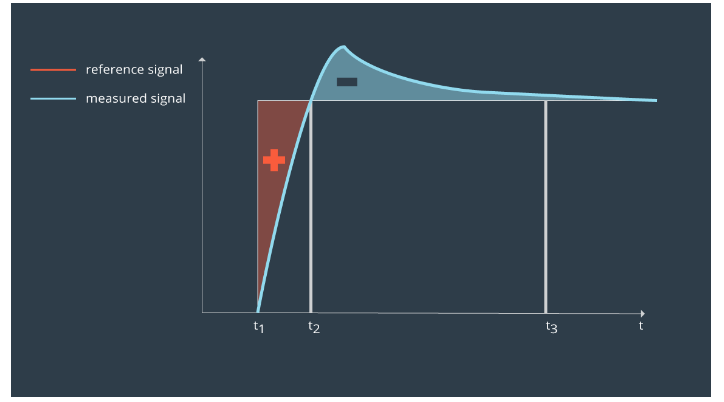

Having seen that the tuned PID controller is prone to winding up the control input due to actuator saturation, we will need to implement an anti-windup scheme to stop the controller from winding up. We will be implementing the **Back-calculation** anti-windup scheme in our PID implementation.

-   Start by adding a $K_b =\frac{1}{T_t }$ gain block in the PID loop, as shown above in the schematic.

-   Now set a non-zero $K_b$ value below and run this section. (Note: A very large value of $K_b$ can make Simulink crash. Keep your choice for $K_b$ value below 1000).

-   Now try re-tuning the PID controller in the previous section.


Kb = 0; % Back Calculation Gain

set_param(gcs, 'SimulationCommand', 'update');

## Gain Scheduling PID

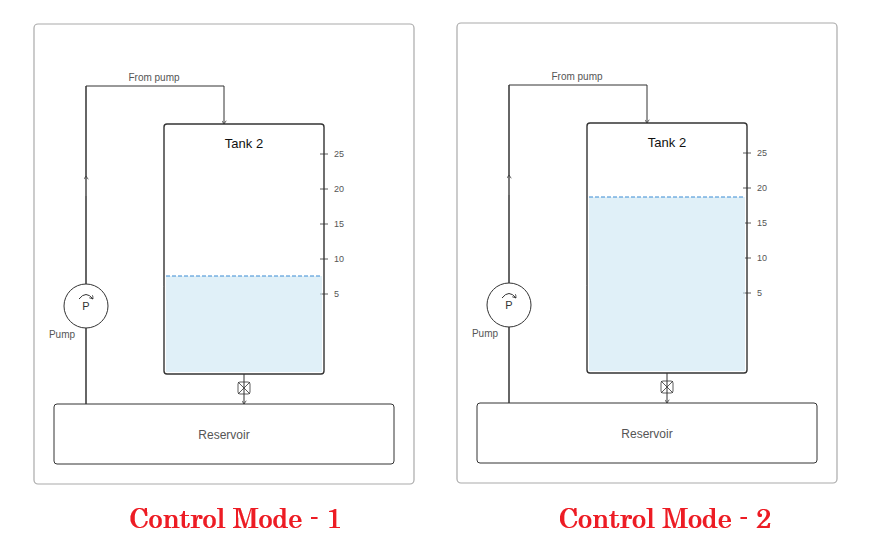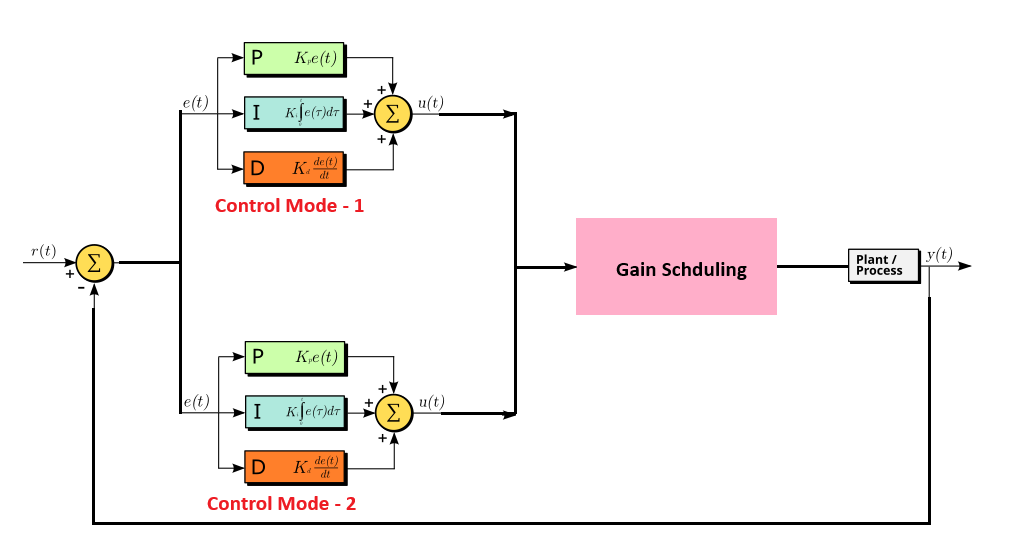

In this section we will be performing gain scheduling to perform PID mode transition from a fast responding controller to a more cautious controller that has no over shoot as we approach closer to the tank brim, in order to avoid any over flow.

-   Start by finding the gains for a fast responding PID controller at a reference height of **12cm** and a slow PID controller at a reference height of **22cm**.

-   Now create a copy of the PID controller in the Simulink workspace and connect the two PID controllers in parallel, as shown in the schematic above. Set their gains to be equal to the corresponding gains that you found for fast and slow controllers.

-   Now uncomment the **Gain Scheduling** block and make connections for the reference error and output signal. Run your system to see if your tuned gains worke for this system.


C = 1; % Control Mode


Ref = 0; % Reference Height
V = 0; % Pump Input Voltage


P =0;
I =0;
D =0;

P2 =0;
I2 =0;
D2 =0;

set_param(gcs, 'SimulationCommand', 'update');
